close all
clear all
clc

%% Import dati
opts=detectImportOptions('./data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
dati=readtable('./data/MiniProjectEFSA.xlsx', opts);
dati.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

dose=[0, 30, 100, 150];

dati_male_1 = dati(dati.endpoint==1&dati.sex==0,:);
dati_female_1 = dati(dati.endpoint==1&dati.sex==1,:);
dati_male_2 = dati(dati.endpoint==2&dati.sex==0,:);
dati_female_2 = dati(dati.endpoint==2&dati.sex==1,:);
dati_male_3 = dati(dati.endpoint==3&dati.sex==0,:);
dati_female_3 = dati(dati.endpoint==3&dati.sex==1,:);

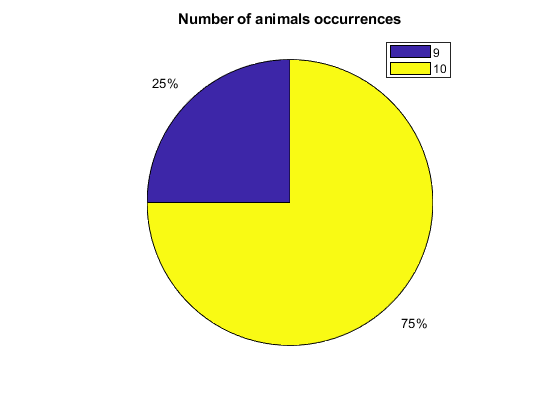

figure
pie(groupcounts(dati.numberOfAnimals),"%.f%%")
title('Number of animals occurrences')
legend("9","10")

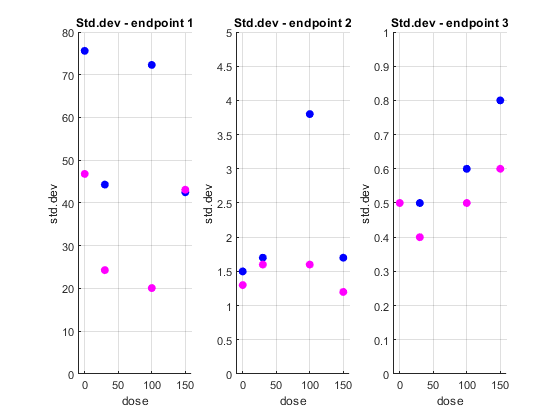

figure
subplot(1,3,1)
scatter(dose,dati_male_1.SD,'blue',"filled")
hold on
scatter(dose,dati_female_1.SD,'magenta',"filled")
grid on
xlim([-10 160])
ylim([0 80])
title("Std.dev - endpoint 1")
xlabel("dose")
ylabel("std.dev")

subplot(1,3,2)
scatter(dose,dati_male_2.SD,'blue',"filled")
hold on
scatter(dose,dati_female_2.SD,'magenta',"filled")
grid on
xlim([-10 160])
ylim([0 5])
title("Std.dev - endpoint 2")
xlabel("dose")
ylabel("std.dev")

subplot(1,3,3)
scatter(dose,dati_male_3.SD,'blue',"filled")
hold on
scatter(dose,dati_female_3.SD,'magenta',"filled")
grid on
xlim([-10 160])
ylim([0 1])
title("Std.dev - endpoint 3")
xlabel("dose")
ylabel("std.dev")

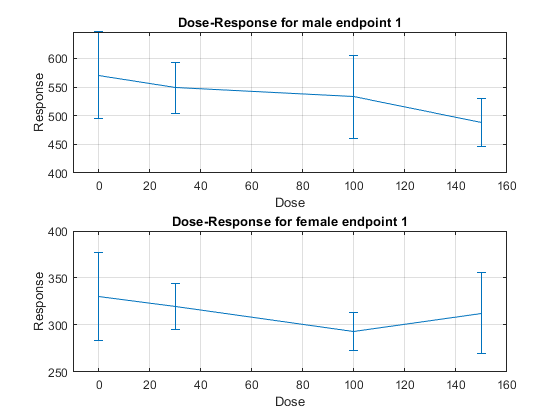

%% Plotting dose-responde for endpoint-gender

%Endpoint 1
figure
subplot(2,1,1)
plot(dose,dati_male_1.response);
errorbar(dose,dati_male_1.response,dati_male_1.SD)
xlim([-10 160])
grid on
title('Dose-Response for male endpoint 1')
xlabel('Dose')
ylabel('Response')

subplot(2,1,2)
plot(dose,dati_female_1.response);
errorbar(dose,dati_female_1.response,dati_female_1.SD)
grid on
xlim([-10 160])
title('Dose-Response for female endpoint 1')
xlabel('Dose')
ylabel('Response')

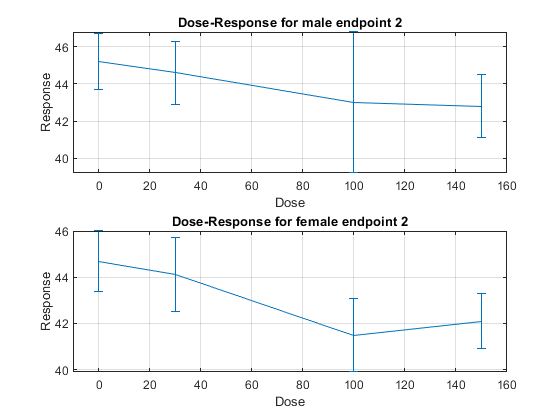

%Endpoint 2 
figure
subplot(2,1,1)
plot(dose,dati_male_2.response);
errorbar(dose,dati_male_2.response,dati_male_2.SD)
grid on
xlim([-10 160])
title('Dose-Response for male endpoint 2')
xlabel('Dose')
ylabel('Response')

subplot(2,1,2)
plot(dose,dati_female_2.response);
errorbar(dose,dati_female_2.response,dati_female_2.SD)
grid on
xlim([-10 160])
title('Dose-Response for female endpoint 2')
xlabel('Dose')
ylabel('Response')

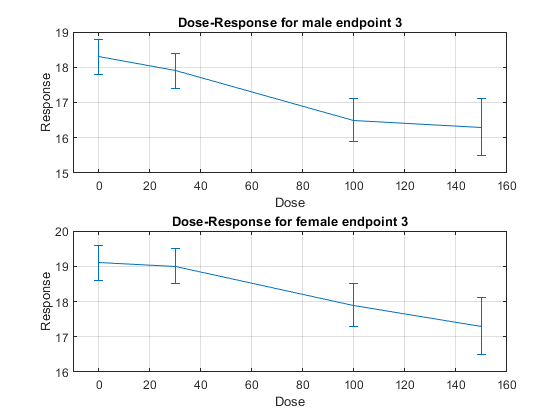

%Endpoint 3
figure
subplot(2,1,1)
plot(dose,dati_male_3.response);
errorbar(dose,dati_male_3.response,dati_male_3.SD)
grid on
xlim([-10 160])
title('Dose-Response for male endpoint 3')
xlabel('Dose')
ylabel('Response')

subplot(2,1,2)
plot(dose,dati_female_3.response);
errorbar(dose,dati_female_3.response,dati_male_3.SD)
grid on
xlim([-10 160])
title('Dose-Response for female endpoint 3')
xlabel('Dose')
ylabel('Response')